# **Problem 4:**

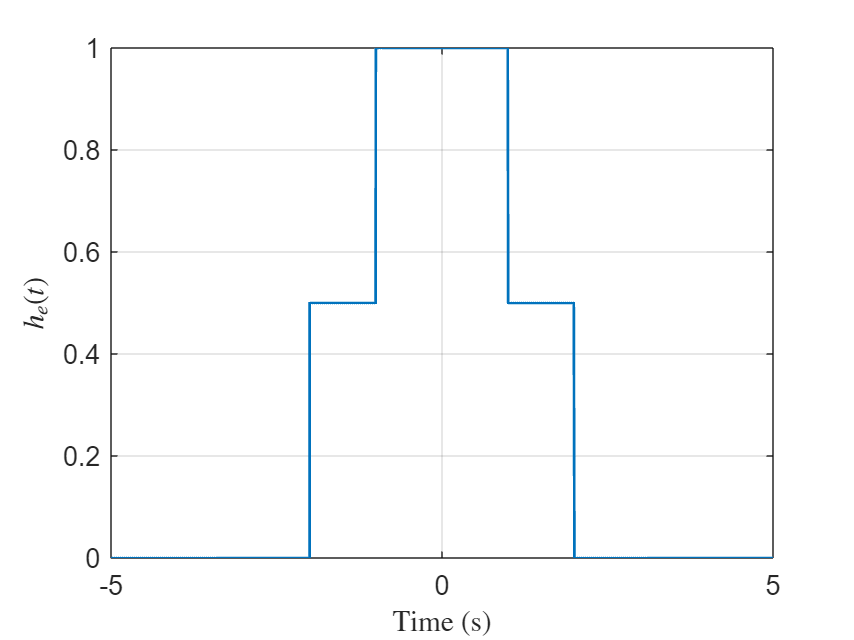

clc;
clear all;

dt=0.0001;
t=-5:dt:5;
N = length(t);

h_e = 0.5*(heaviside(t+1)-heaviside(t-1)+heaviside(t+2)-heaviside(t-2));
figure(1)
plot ( t,h_e,'LineWidth',1);
ylabel('$h_e (t)$','FontWeight','bold','Interpreter','latex');
xlabel('Time (s)','FontWeight','bold','Interpreter','latex');
grid on;

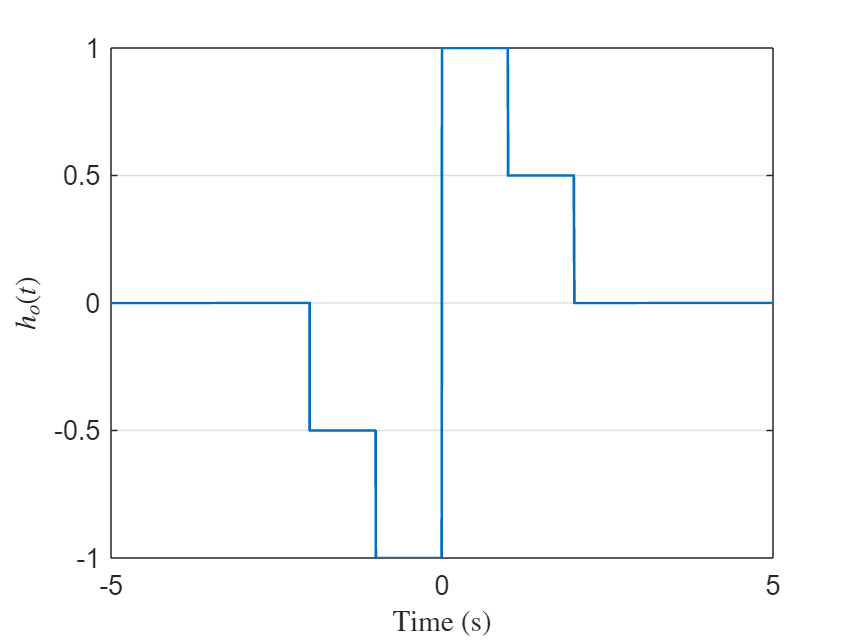

h_o = -0.5*(heaviside(t+2)+heaviside(t+1))+2*heaviside(t)-0.5*(heaviside(t-1)+heaviside(t-2));
figure(2)
plot ( t,h_o,'LineWidth',1);
ylabel('$h_o (t)$','FontWeight','bold','Interpreter','latex');
xlabel('Time (s)','FontWeight','bold','Interpreter','latex');
grid on;

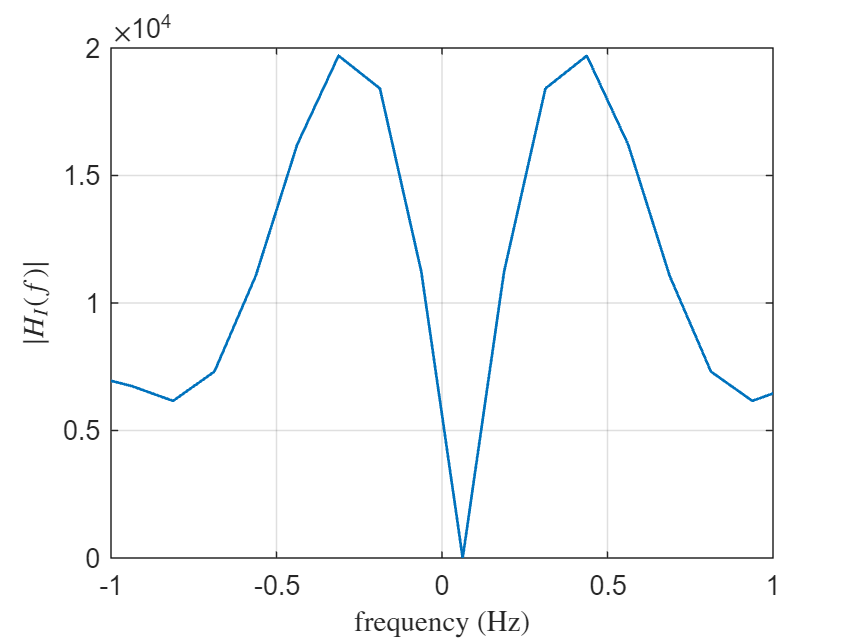



NFFT=2^nextpow2(N);
n=NFFT/2;
f=1/8*linspace(-n,n,NFFT);
H_I_f = fftshift(fft((h_o),NFFT));
H_I_f=abs(H_I_f);
figure(3)
plot ( f,H_I_f,'LineWidth',1);
ylabel('$|H_I (f)|$','FontWeight','bold','Interpreter','latex');
xlabel('frequency (Hz)','FontWeight','bold','Interpreter','latex');
xlim([-1,1])
grid on;